## 3. Lançamentos de moeda equilibrada

a)

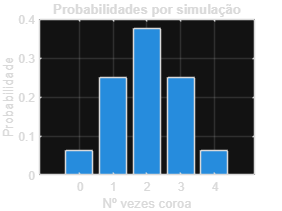

n = 4;
p = 0.5;
N = 1e5;

random = rand(n, N);
coroa = sum(random <= p);

zero = sum(coroa == 0);
um = sum(coroa == 1);
dois = sum(coroa == 2);
tres = sum(coroa == 3);
quatro = sum(coroa == 4);

soma = (zero + um + dois + tres + quatro)/N;

probabilidades = [zero, um, dois, tres, quatro]/N;

x_valores = [0,1,2,3,4];
bar(probabilidades);
grid on;
xticklabels(x_valores);
title('Probabilidades por simulação');
ylabel('Probabilidade');
xlabel('Nº vezes coroa')

### b) Valor esperado | Variância | Desvio padrão

valor_esperado = sum(x_valores .* probabilidades);
variancia = sum((x_valores - valor_esperado).^2 .* probabilidades);
desvio_padrao = sqrt(variancia);

fprintf('O valor esperado é %.3f \nA variância é %.4f \nO desvio padrão é %.4f' ,valor_esperado, variancia, desvio_padrao);

O valor esperado é 1.998 
A variância é 1.0013 
O desvio padrão é 1.0007

c)

%tendo em conta que há um número fixo de tentativas 
%onde só ha sucesso ou falha
%distribuição binomial!
n = 4 ;%numero de lancamentos
p = 0.5 ;%probabilidade de sucesso

k = 0:4; %numero de sucessos
distribuicao = zeros(1,length(k));

for i = 1:length(k)
    %calculo coeficiente binomial
    choose = factorial(n)/(factorial(k(i)) * factorial(n-k(i)));
    %prob
    probabilidade_k = choose * (p^k(i)) * ((1 - p)^(n - k(i)));
    distribuicao(i) = probabilidade_k;
    fprintf('Distribuição bilinear de %d é %.4f \n', k(i), distribuicao(i));
end

Distribuição bilinear de 0 é 0.0625 
Distribuição bilinear de 1 é 0.2500 
Distribuição bilinear de 2 é 0.3750 
Distribuição bilinear de 3 é 0.2500 
Distribuição bilinear de 4 é 0.0625 


k = 4;
probability = nchoosek(n, k) * (p^k) * ((1 - p)^(n - k));
fprintf('A probabilidade de obter %d sucessos em %d ensaios é %f\n', k, n, probability);

A probabilidade de obter 4 sucessos em 4 ensaios é 0.062500


d)

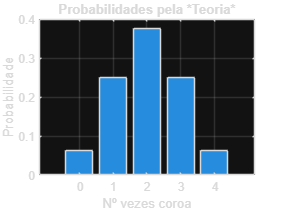

x_valores = [0,1,2,3,4];
bar(distribuicao);
grid on;
xticklabels(x_valores);
title('Probabilidades pela *Teoria*');
ylabel('Probabilidade');
xlabel('Nº vezes coroa')


for i = 1:5
    fprintf('%d | Simulação = %.4f | Teórico = %.4f \n', (i-1), probabilidades(i) ,distribuicao(i));
end

0 | Simulação = 0.0630 | Teórico = 0.0625 
1 | Simulação = 0.2502 | Teórico = 0.2500 
2 | Simulação = 0.3747 | Teórico = 0.3750 
3 | Simulação = 0.2497 | Teórico = 0.2500 
4 | Simulação = 0.0623 | Teórico = 0.0625 


e)

valor_esperado_t = sum(x_valores .* distribuicao);
variancia_t = sum((x_valores - valor_esperado_t).^2 .* distribuicao);
desvio_padrao_t = sqrt(variancia_t);

fprintf('O valor teórico esperado é %.3f | Simulado é %.3f  \nA variância teórica é %.3f | Simulada é %.3f \nO desvio padrão teórico é %.3f | Simulado é %.3f' ,valor_esperado_t,valor_esperado, variancia_t, variancia, desvio_padrao_t, desvio_padrao);

O valor teórico esperado é 2.000 | Simulado é 1.998  
A variância teórica é 1.000 | Simulada é 1.001 
O desvio padrão teórico é 1.000 | Simulado é 1.001

f)

    i)

fprintf('Probabilidade pelo menos duas coroas = %.3f', sum(distribuicao(3:end)));

Probabilidade pelo menos duas coroas = 0.688

    ii)

fprintf('Probabilidade até uma coroa = %.3f', sum(distribuicao(1:2)));

Probabilidade até uma coroa = 0.312

    iii)

fprintf('Probabilidade entre uma até três coroas = %.3f', sum(distribuicao(2:4)));

Probabilidade entre uma até três coroas = 0.875